## Lab 1

#### Harware parameters

T = 0.001; % sampling time (change to fit your experiment)

r = 0.01; % pinion gear radius [m]

Kt = 0.028; % torque constant for the EMB-AM2 actuator [Nm/A]

motor_eff = 1.0; % system efficiency (change to match your plant)

Kt = Kt*motor_eff; % including efficiency, actual Kt used in Simulink


### Experiment 1: Quasi-statif determination of spring rates

S = 10;   % simulation duration time (change to fit your experiment)

t = 0:T:S;          % total time
y = zeros(size(t)); % output

slope = 5           % N/s  | Change the slope here

slope = 5


% Delay
delay = 1         % seconds

delay = 1

delay_t = 0:T:delay

delay_t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


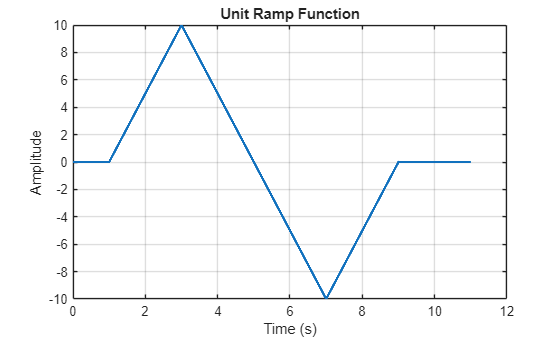


% Ramp
idx1 = (t >= 0) & (t < 2);
y(idx1) = t(idx1).*slope;

% Two sided
idx2 = (t >= 2) & (t < 4);
y(idx2) = t(idx2) .* -slope + slope*4;

% Mirrored
idx3 = (t >= 4) & (t < 6);
y(idx3) = (t(idx3) - 4) .* -slope;

% Mirrored Two-sided
idx4 = (t >= 6) & (t < 8);
y(idx4) = (t(idx4) - 6) .* slope - slope*2;

% delay y
y_delayed = [zeros(size(delay_t)), y(2:end)]; 
t = 0:T:S+delay;
size(t);
size(y_delayed);

plot(t, y_delayed, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Amplitude');
title('Unit Ramp Function');
grid on;


sim_input = timeseries(y_delayed', t');

% Define parameters
model_name = 'MSE_LAB_FORCE_INPUT_DAQ2';
S = 8; 

% Load and configure for Real-Time / External mode
load_system(model_name);

Error using load_system (line 23)
Unable to find system or file 'MSE_LAB_FORCE_INPUT_DAQ2'.

set_param(model_name, 'SimulationMode', 'external');

set_param(model_name, 'StopTime', num2str(S));

% Execute
set_param(model_name,'SimulationCommand','start')

#### Plots

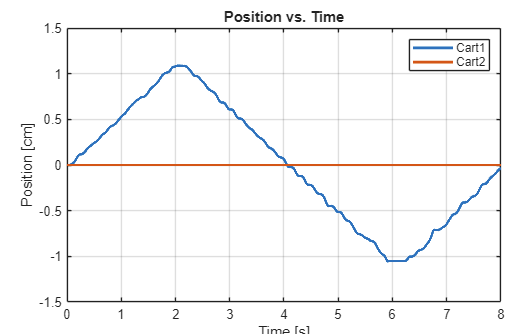

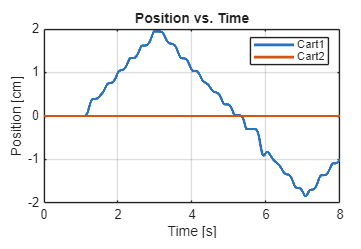

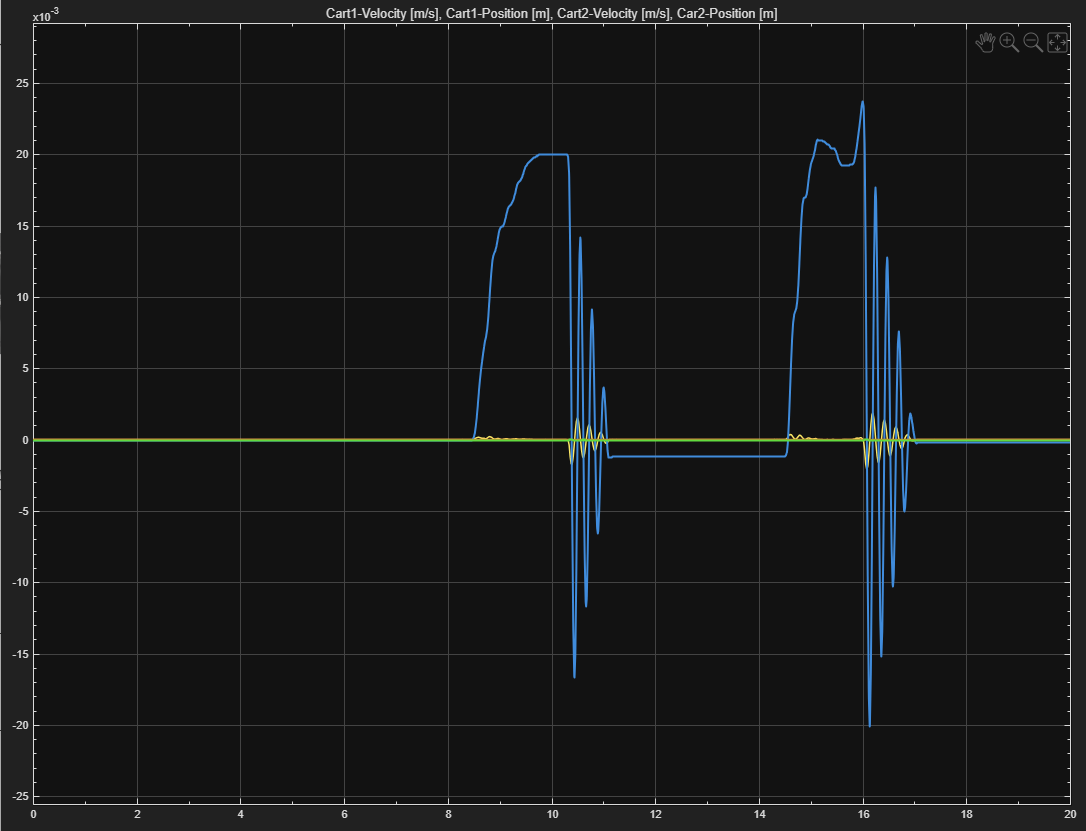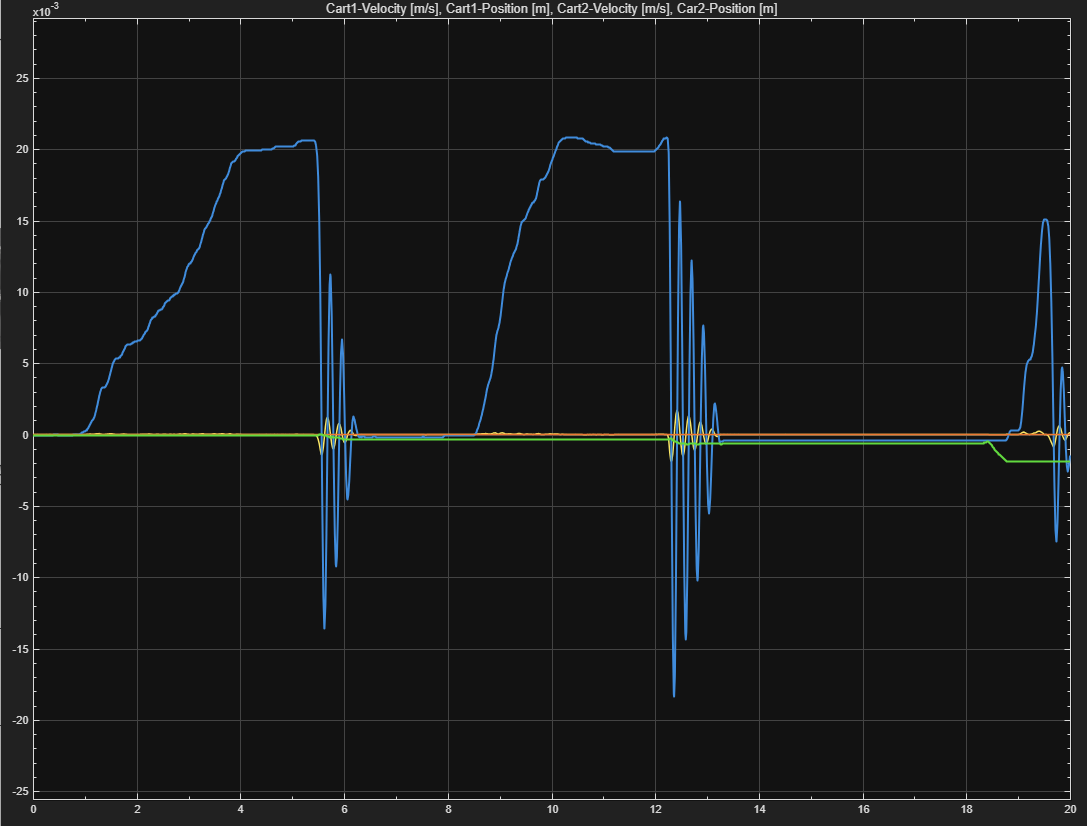

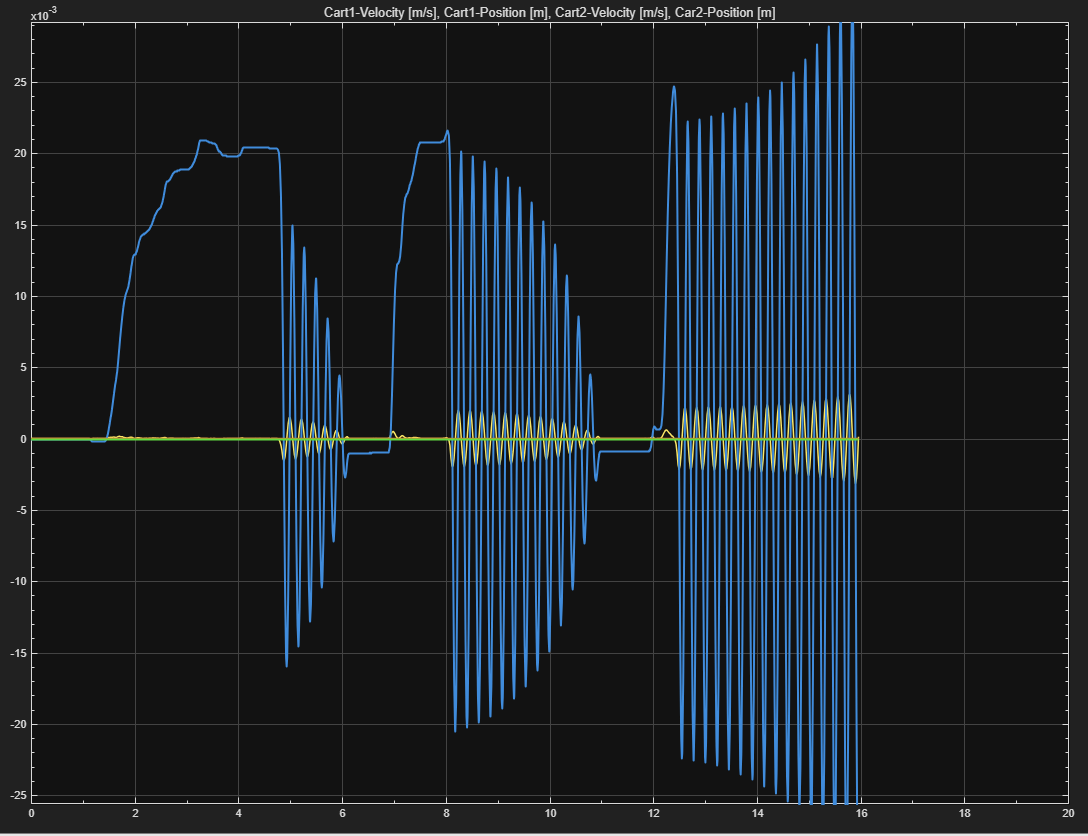

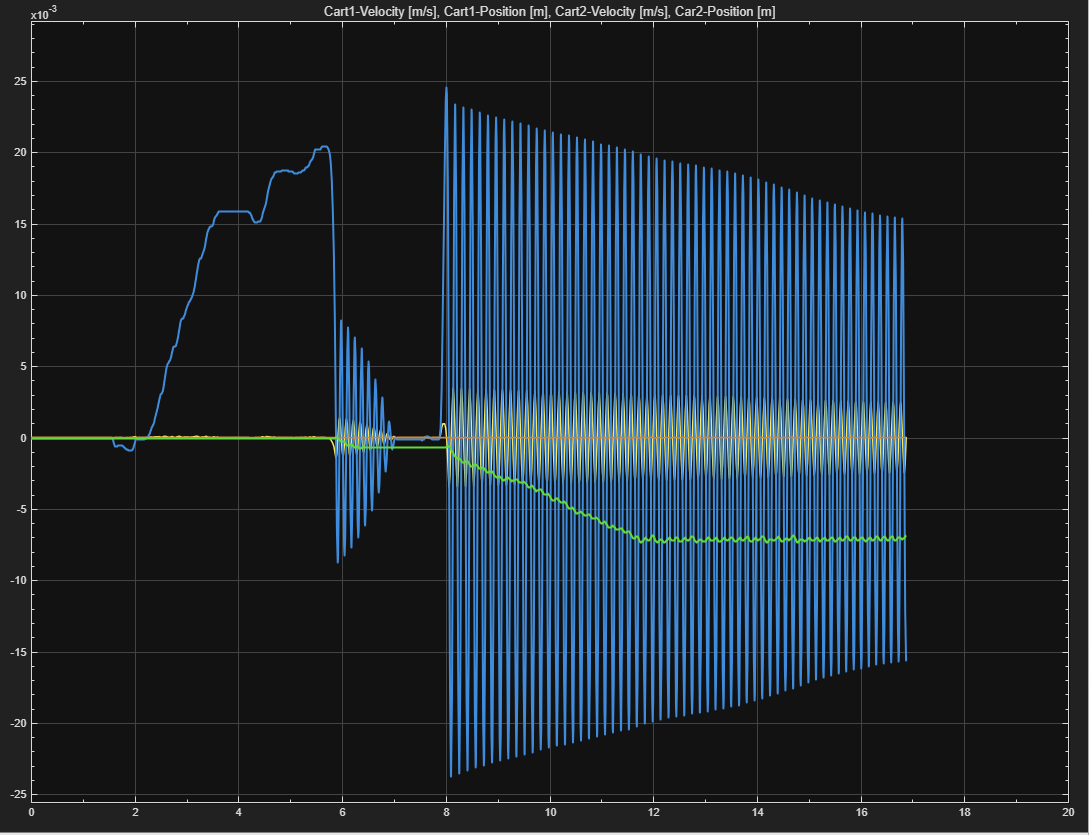

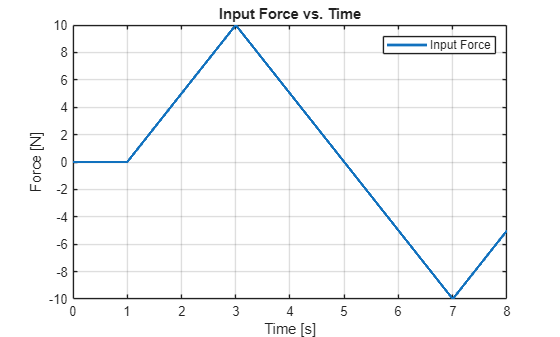



%% PLOTTING - Input Force

plot(rt_time, f_input,'LineWidth',2);
title('Input Force vs. Time');
xlabel('Time [s]');
ylabel('Force [N]');
legend('Input Force');
grid on;

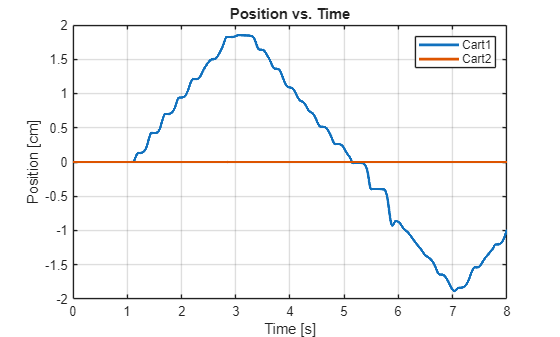


%% PLOTTING - Position for both Carts
plot(rt_time, cart1_position*100, rt_time, cart2_position*100,'LineWidth',2);
title('Position vs. Time');
xlabel('Time [s]');
ylabel('Position [cm]');
legend('Cart1','Cart2');
grid on;

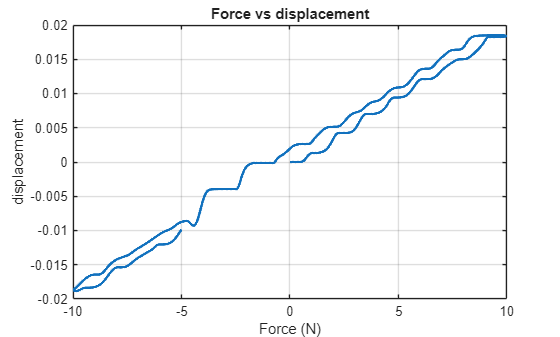


plot(f_input, cart1_position, 'LineWidth', 2);
title('Force vs displacement');
xlabel('Force (N)')
ylabel('displacement')
grid on;

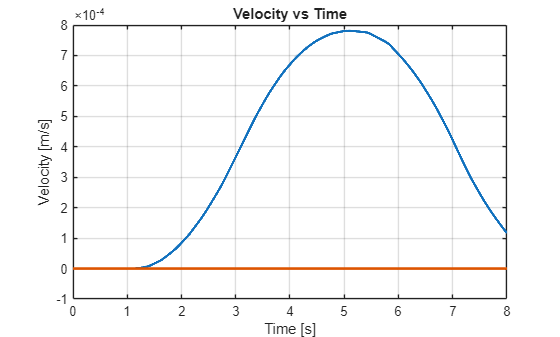


plot(rt_time, cart1_velocity, rt_time, cart2_velocity, 'LineWidth', 2);
title('Velocity vs Time');
xlabel('Time [s]')
ylabel('Velocity [m/s]')
grid on;

### Experiment 2

Zero output: 

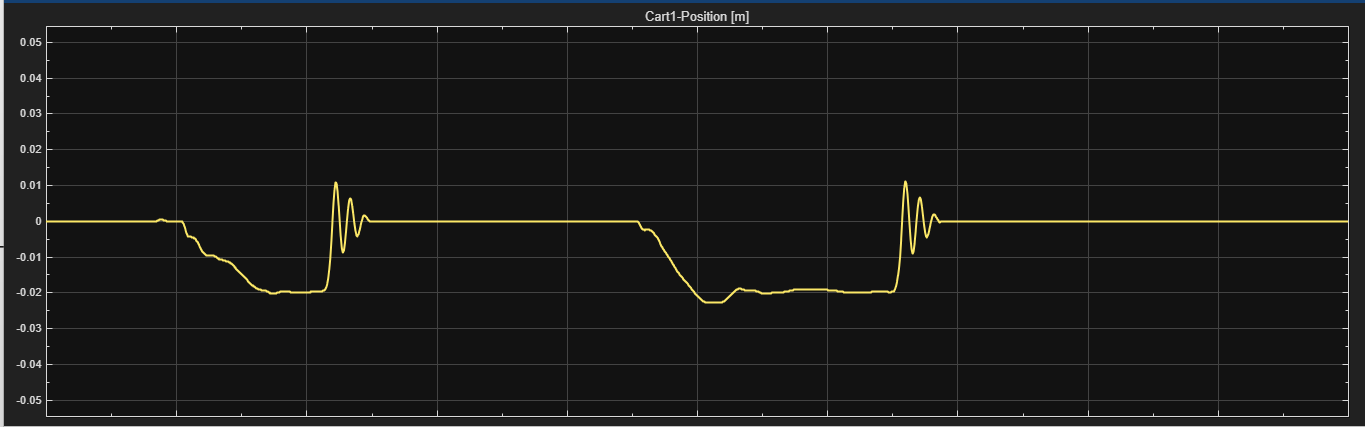

%% ============================================================
% EXPERIMENT 2 - FREE VIBRATION / DISPLACEMENT DECAY
% Cart 1 is manually displaced before running
% =============================================================

clear;
clc;
close all;

%% Hardware Parameters

T = 0.001;                  % Sampling time [s]

r = 0.01;                   % Pinion gear radius [m]

Kt = 0.028;                 % EMB-AM2 torque constant [Nm/A]

motor_eff = 1.0;            % System efficiency

Kt = Kt*motor_eff;

%% Experiment Parameters

S = 20;                     % Test duration [s]

%% Load Model

model_name = 'Lab1_exp_2';

load_system(model_name);

set_param(model_name,'SimulationMode','external');
set_param(model_name,'StopTime',num2str(S));

%% Start Experiment

disp('Cart 1 should already be displaced.');

Cart 1 should already be displaced.


disp('Starting free vibration test...');

Starting free vibration test...



set_param(model_name,'SimulationCommand','start');

%% Wait for Completion

disp('Collecting data...');


while strcmp(get_param(model_name,'SimulationStatus'),'running')
    pause(0.1);
end

disp('Experiment Complete.');

Experiment Complete.


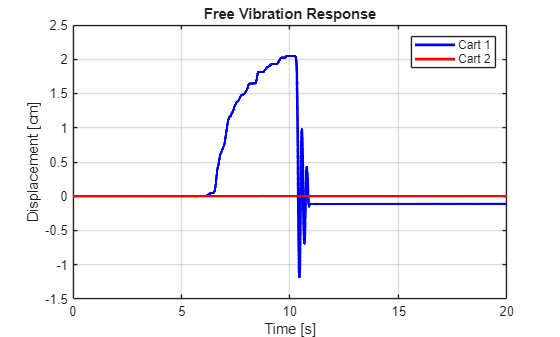

%% ============================================================
% DISPLACEMENT RESPONSE
% =============================================================

figure;

plot(rt_time1,cart1_position1*100,...
    'b','LineWidth',2);

hold on;

plot(rt_time1,cart2_position1*100,...
    'r','LineWidth',2);

title('Free Vibration Response');
xlabel('Time [s]');
ylabel('Displacement [cm]');
legend('Cart 1','Cart 2');
grid on;

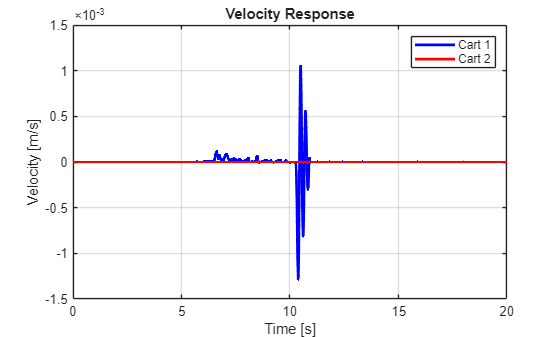


%% ============================================================
% VELOCITY RESPONSE (OPTIONAL)
% =============================================================

figure;

plot(rt_time1,cart1_velocity,...
    'b','LineWidth',2);

hold on;

plot(rt_time1,cart2_velocity,...
    'r','LineWidth',2);

title('Velocity Response');
xlabel('Time [s]');
ylabel('Velocity [m/s]');
legend('Cart 1','Cart 2');
grid on;

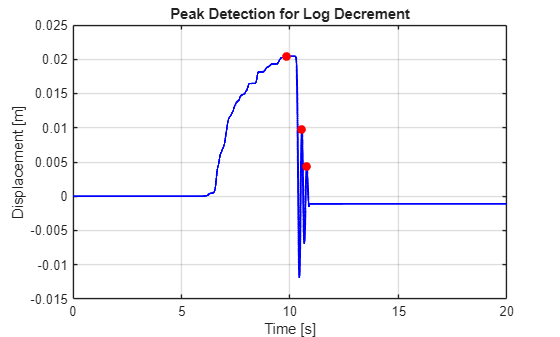


%% ============================================================
% LOG DECREMENT ANALYSIS
% USING CART 1 DISPLACEMENT
% =============================================================

x = cart1_position1;
t = rt_time1;

[pks,locs] = findpeaks(x,t,...
    'MinPeakProminence',0.05*max(abs(x)));

%% Plot Detected Peaks

figure;

plot(t,x,'b','LineWidth',1.5);
hold on;

plot(locs,pks,...
    'ro',...
    'MarkerFaceColor','r');

title('Peak Detection for Log Decrement');
xlabel('Time [s]');
ylabel('Displacement [m]');
grid on;


%% Damping Ratio Calculation

n = length(pks)-1;

if n >= 1

    x1 = pks(1);
    xn = pks(end);

    delta = (1/n)*log(x1/xn);

    zeta = delta/sqrt(4*pi^2 + delta^2);

    fprintf('\n');
    fprintf('========== LOG DECREMENT RESULTS ==========\n');
    fprintf('Number of cycles used: %d\n',n);
    fprintf('First peak: %.6f m\n',x1);
    fprintf('Last peak : %.6f m\n',xn);
    fprintf('Log decrement: %.6f\n',delta);
    fprintf('Damping ratio: %.6f\n',zeta);

    %% Natural Frequency Estimate

    Td = mean(diff(locs));

    fd = 1/Td;
    wd = 2*pi*fd;

    wn = wd/sqrt(1-zeta^2);

    fprintf('Damped Frequency: %.3f Hz\n',fd);
    fprintf('Damped Angular Frequency: %.3f rad/s\n',wd);
    fprintf('Natural Frequency: %.3f rad/s\n',wn);
    fprintf('===========================================\n');

else

    warning('Not enough peaks detected for damping calculation.');

end

========== LOG DECREMENT RESULTS ==========


Number of cycles used: 2


First peak: 0.020457 m


Last peak : 0.004274 m


Log decrement: 0.782929


Damping ratio: 0.123651


Damped Frequency: 2.188 Hz


Damped Angular Frequency: 13.749 rad/s


Natural Frequency: 13.855 rad/s
